# Lab 7:  PWM Speed Control of a Motor

## Calculations 

% State-soace model description 
    R = 0.1;     % ohms
    L = 0.1;     % H
    K = 0.01;    % unitless 
    J = (K^2)/L;      % kg.m^2/s^2
    
    A = [-R/L, -K/L; 
          K/J,  0 ]; 
    B = [1/L; 0]; 
    
    C = [0, 1]; 
    D = 0; 
    
%     dx = zeros(2,1); 
%     dx = A*x + B*u; 
%     
%     y = [0, 1]*x; 

% Decay  rate 
sig = R/(2*L)

sig =    0.500000000000000


% Time constant, tau = 1/sigma
Tau = 1/sig 

Tau =      2


% DC Amplification

DC_amp = K/(J*L)

DC_amp =    100


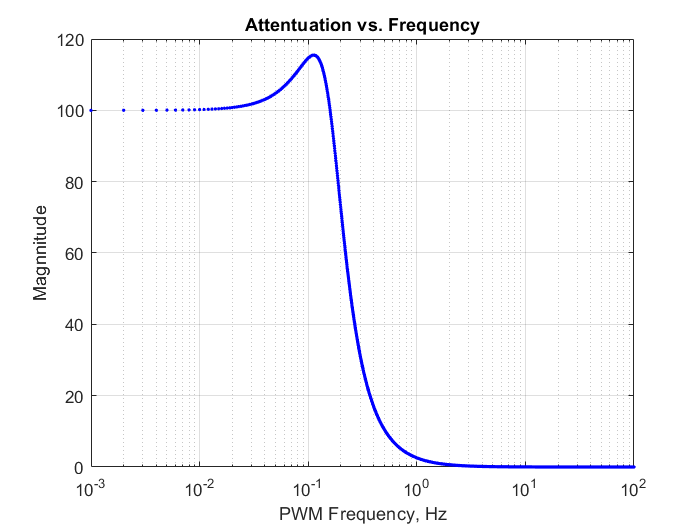

% Attenuation for different  frequencies

num = K/(J*L);
den = [1, R/L, (K^2/(J*L))] ;

f = 0:0.001:100;
s = 1i*2*pi*(f); 
G_mag = abs(polyval(num,s)./polyval(den,s)); 

semilogx(f, G_mag, 'b.'); 
grid on; 
xlabel('PWM Frequency, Hz'); 
ylabel('Magnnitude'); 
title('Attentuation vs. Frequency')

% Attenuation for f= 100 Hz 
G_f = G_mag(end)

G_f =      2.533032799175867e-04


% This means there are almost no oscillations at steady state. Their
% magnitudes are very small. For f < 1 Hz, it is the opposite. 



## Lab Assignment

## 1.  & 2. 

The blue plot is the PWM  input, red the rsponse of the system. With $\tau = 2$, the system reaches steady state around 8 seconds. 

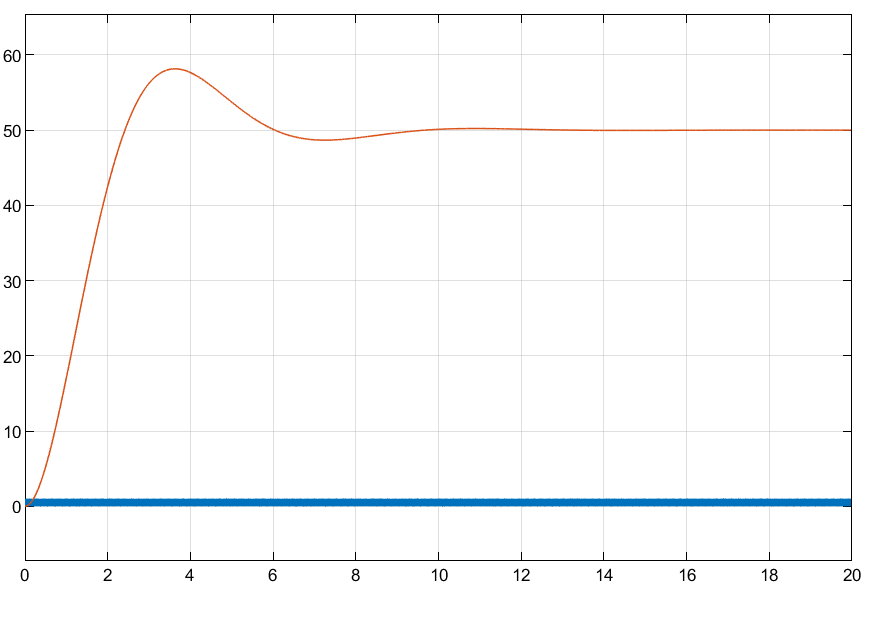

Zoomed in PWM input with response. 

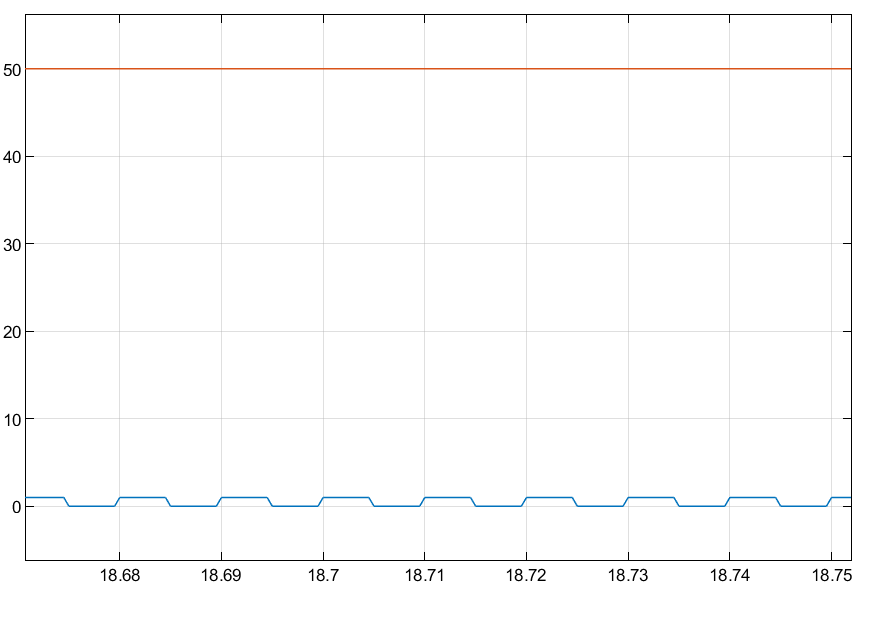

Zooming in to the response: It is clear there are still fast oscialltions with small amplituses. 

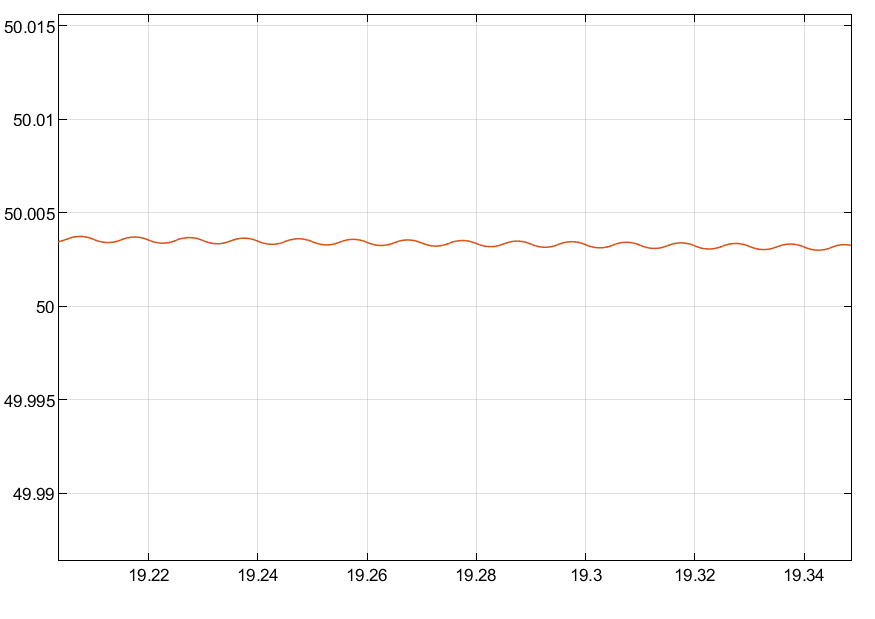

## 3.  PWM width = 10%

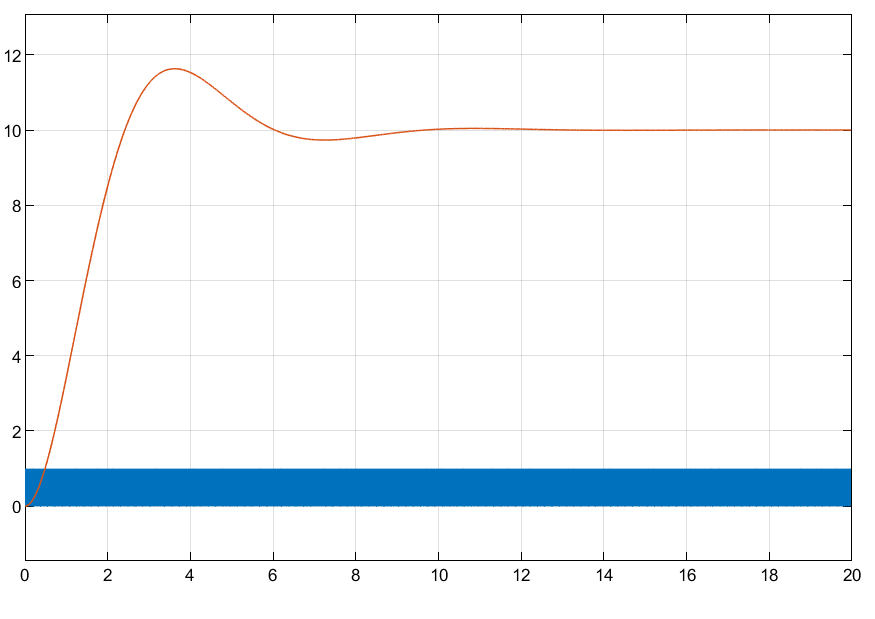

## Questions

-  DC gain is determied by K

- J does not change DC gain or decay rate. 

- To change decay rate without changing the the natural frequency requires changing only the value of R. This is becasue the decay rate depends on both R and L, while the DC natural frequency depends on J and L. $\sigma = \frac{R}{2L} =1  \Rightarrow R = 2L = 0.2$

 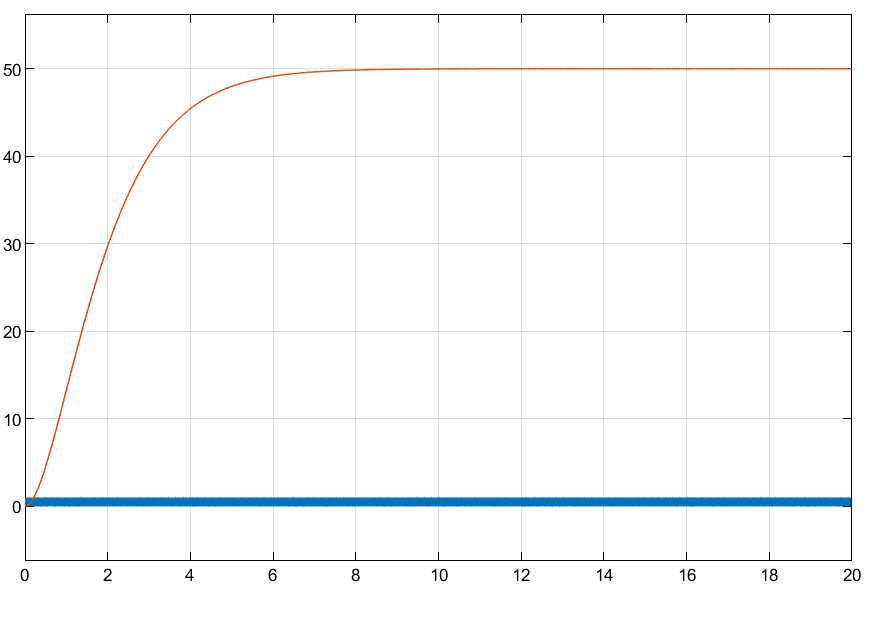

It is clear that the system reaches steady-state faster with this bigger decay rate. 

Also, it does not overshoot. Decreasing R decreases the decay rate and the system osciallates more, as shown in the figure below.